## What is the stability limit for a fly with augmented feedback?

clear ; close all ; clc
syms s K tau gamma
assume([K tau gamma], 'real')
assume([K tau] > 0)

Define the plant$\;P\left(s\right)$ as a lowpass filter with time constant $\tau$ and unity gain

P = 1 / (tau*s + 1)

$$P = \frac{1}{s\,\tau +1}$$

Define the controller$\;C\left(s\right)$ as a proportional controller $K$

C = K

$$C = K$$

Define the open-loop system$\;G\left(s\right)=P\left(s\right)C\left(s\right)$

G = P * C

$$G = \frac{K}{s\,\tau +1}$$

Define the closed-loop system$H\left(s\right)$with augmented feedback $\gamma$ as a function of the open-loop system $G\left(s\right)$

H = G / (1 - G*(-1 + gamma));
H = collect(simplify(H), s)

$$H = \frac{-K}{\left(-\tau \right)\,s+K\,\gamma -K-1}$$

Pull out the characteristic polynomial

[~,D] = numden(H)

$$D = K-K\,\gamma +s\,\tau +1$$

Set to 0 and solve for the pole $s$

ss = solve(D == 0, s)

$$ss = -\frac{K-K\,\gamma +1}{\tau }$$

Find $\gamma$ when system goes unstable by setting $s=0$

pole_crit = solve(ss == 0, gamma)

$$pole\_crit = \frac{K+1}{K}$$

Substitue numeric values of $\tau =0\ldotp 155$ and $K=4$

tau_num = 0.155;
K_num = 4;
pole_crit = subs(pole_crit, [tau K], [tau_num K_num]);
pole_crit = vpa(pole_crit,3)

$$pole\_crit = 1.25$$

## Incorporating a time delay

### Time delay model

Gtest = G*exp(-t_d*s)

$$Gtest = \frac{K\,{\mathrm{e}}^{-\frac{s}{50}}}{s\,\tau +1}$$

Htest = Gtest / (1 + Gtest*(-1 + gamma))

$$Htest = \frac{K\,{\mathrm{e}}^{-\frac{s}{50}}}{\left(\frac{K\,{\mathrm{e}}^{-\frac{s}{50}}\,\left(\gamma -1\right)}{s\,\tau +1}+1\right)\,\left(s\,\tau +1\right)}$$

Htest = simplify(expand(Htest))

$$Htest = \frac{K}{{\mathrm{e}}^{s/50}-K+K\,\gamma +s\,\tau \,{\mathrm{e}}^{s/50}}$$

### Assess stability using numerical methods.

Set the time delay

t_d = 0.02; % 20 ms delay for flies

Substitue numeric values of $\tau =0\ldotp 155$ and $K=4$ into $G\left(s\right)$, convert to transfer function object and add time delay

G_num = subs(G, [tau K], [tau_num K_num]);
Gtf = minreal(sym2tf(G_num));
Gtf.IODelay = t_d;
% Gtf = pade(Gtf, 4);

Pick range of $\gamma$ to test

% gamma_test = [-3 -2 -1 0 1.2 1.25 1.3 1.4 1.5]';
gamma_test = [-3 -2 -1 0 0.5 0.75 1 1.2]';
n_gamma = length(gamma_test);

Simulate system for all gammas

fv = logspace(-10, 5, 10500)';
wv = 2*pi*fv;
n_fv = 2*length(fv);

Real = nan(n_fv,n_gamma);
Imag = nan(n_fv,n_gamma);
HGain = nan(n_fv/2,n_gamma);
HPhase = nan(n_fv/2,n_gamma);
HError = nan(n_fv/2,n_gamma);
Ntf = cell(n_gamma,1);
Htf = cell(n_gamma,1);
stable = false(n_gamma,1);
for g = 1:n_gamma
    Ntf{g} = minreal( -Gtf*(-1 + gamma_test(g)) );
    [R,I] = nyquist(Ntf{g}, wv);
    R = squeeze(R);
    I = squeeze(I);
    Real(:,g) = [R ; flipud(R)];
    Imag(:,g) = [I ; flipud(-I)];
    
    Htf{g} = minreal( Gtf / (1 - Gtf*(-1 + gamma_test(g))) );
    
    Htf{g} = minreal( Gtf / (1 - Gtf*(-1 + gamma_test(g))) );
    [gain,phase] = bode(Htf{g}, wv);
    gain = squeeze(gain);
    phase = squeeze(phase);
    HGain(:,g) = gain;
    HPhase(:,g) = phase;
    
    Hs = HGain(:,g).*exp(deg2rad(HPhase(:,g))*1j);
    HError(:,g) = abs(1 + Hs*(-1 + gamma_test(g)));
    %stable(g) = isstable(Htf{g});
end

crit_point = find(~stable, 1, 'first');
gamma_test(crit_point)

ans = -3

### Nyquist plot

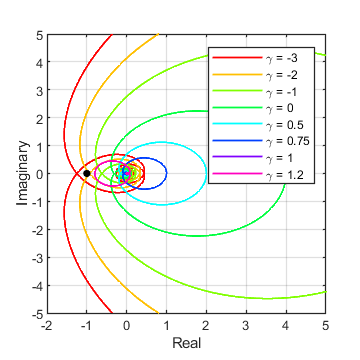

fig = figure (1) ; clf
set(fig, 'Color', 'w', 'Visible', 'on', 'Units', 'inches', 'Position', [3 3 3 3])
clear ax h
ax = subplot(1,1,1); hold on ; cla
axis square
xlabel('Real')
ylabel('Imaginary')

cc = hsv(n_gamma);
h = gobjects(1,n_gamma);
for g = 1:n_gamma
    h(:,g) = plot(Real(:,g), Imag(:,g), 'Color', cc(g,:));
end
set(ax, 'Color', 'none', 'LineWidth', 0.75, 'FontSize', 8, 'Box', 'on', 'XGrid', 'on', 'YGrid', 'on')
set(h, 'LineWIdth', 1)
set(ax, 'YLim', 5*[-1 1], 'YTick', -10:1:10)
set(ax, 'XLim', [-2 5], 'XTick', -10:1:10)

plot(-1, 0, 'k.', 'MarkerFaceColor', 'none', 'MarkerSize', 15)
% xline(-1, '--k', 'LineWidth', 2);
legend(h, "\gamma = " + string(gamma_test) )

### Bode plot

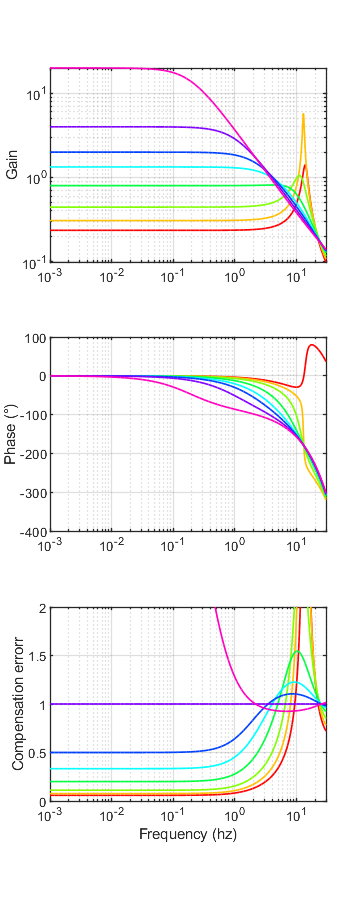

fig = figure (2) ; clf
set(fig, 'Color', 'w', 'Visible', 'on', 'Units', 'inches', 'Position', [3 3 3 2.5*3])
clear ax h

cc = hsv(n_gamma);
ax(1,1) = subplot(3,1,1); hold on ; cla ; ylabel('Gain')
    h.gain = gobjects(1,n_gamma);
    for g = 1:n_gamma
        h.gain(:,g) = plot(fv, HGain(:,g), 'Color', cc(g,:));
    end
    
ax(2,1) = subplot(3,1,2); hold on ; cla ; ylabel('Phase (°)')
    h.phase = gobjects(1,n_gamma);
    for g = 1:n_gamma
        h.phase(:,g) = plot(fv, HPhase(:,g), 'Color', cc(g,:));
    end
    
ax(3,1) = subplot(3,1,3); hold on ; cla ; ylabel('Compensation errorr')
    h.error = gobjects(1,n_gamma);
    for g = 1:n_gamma
        h.error(:,g) = plot(fv, HError(:,g), 'Color', cc(g,:));
    end
    
xlabel('Frequency (hz)')    
set(ax, 'Color', 'none', 'LineWidth', 0.75, 'FontSize', 8, 'Box', 'on', 'XGrid', 'on', 'YGrid', 'on')
set([h.gain h.phase h.error], 'LineWidth', 1)
set(ax, 'XScale', 'log', 'XLim', [0.001 30], 'XTick', 10.^(-3:3))
set(ax(1), 'YScale', 'log')
set(ax(3), 'YLim', [0 2], 'YTick', 0:0.5:10)

% leg = legend(h.phase, "\gamma = " + string(gamma_test) );
% leg.Position = [0.1682    0.1253    0.2993    0.2290];